# Create Controller Using Stateflow Blocks and Simulate

The revised model is using Stateflow for the logic to handle the system's fault logic.  

Similar to the first model, this model will use ad-hoc testing and the Simulink **Dashboard** blocks to verify the behavior of the fault logic.

### The main topics to cover for this exercise are:

- Adding action statements to Stateflow;

- Testing the model using **Dashboard** blocks;

  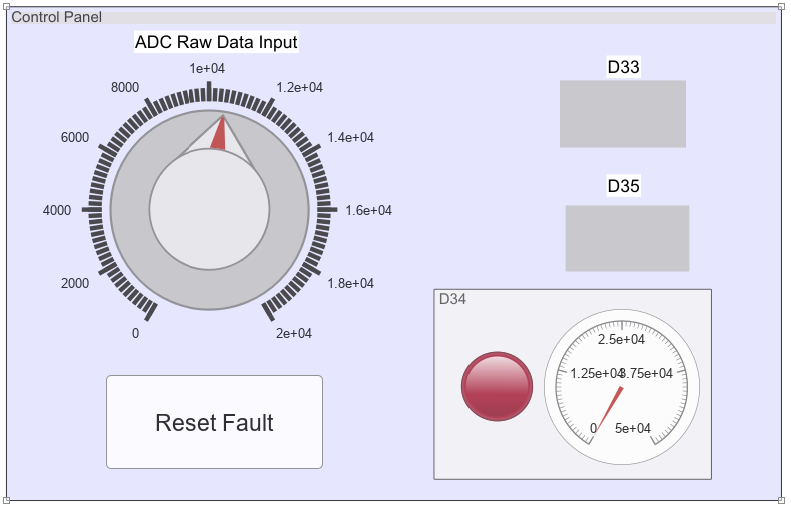                           

open_system('Exercise2_Start');

The opened model includes part of the** FaultLogic** subsystem that will be used in future exercises, along with other necessary instructions. The model already has been configured to run the **Dashboard** blocks to control the model, and Simulation Pacing to slow down the simulation to be close to real time.  You will be adding Stateflow action statements to the **FaultLogic** subsystem's Stateflow chart.

### Requirements for the next exercise:

- Add entry action statements in the Stateflow chart.

- Simulate the model, using the **Control Panel** to perform ad-hoc testing.

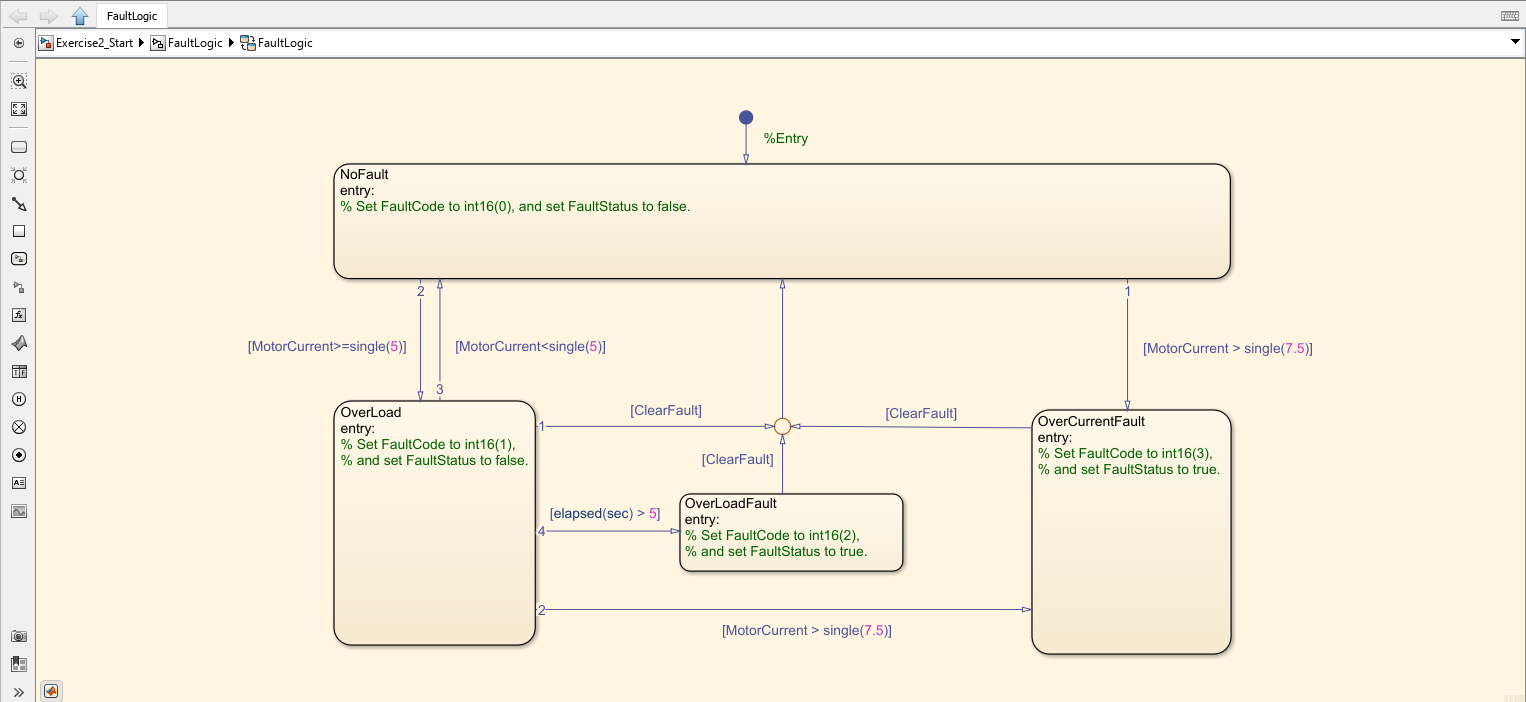

## Add the Stateflow Action Statements

The Stateflow chart is in Exercise2_Start -> FaultLogic -> FaultLogic

- Open the Stateflow chart by clicking on it.

- The Stateflow logic structure is already completed.

- Add the FaultCode and FaultStatus settings to the NoFault, OverLoad, OverLoadFault, and OverCurrentFault state entry actions.

- *Hint:*  FaultCode is a signed 16 bit integer, so it needs to be set with using a typecast, such as this:  int16(5).  

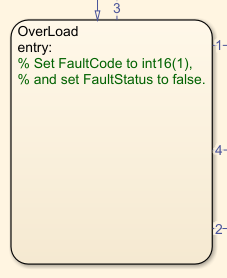

## Test The Algorithm

At this point, we can use the dashboard blocks to test the algorithm as in Exercise 1.

For this ad-hoc testing:

- Return to top level of model

- Click on the **Run** button.

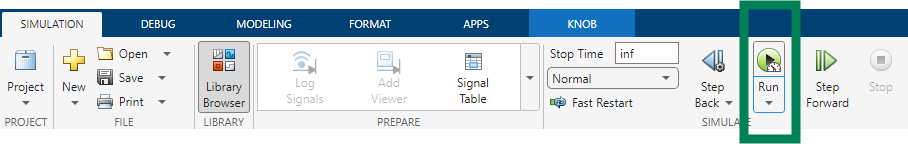

After the model starts running, attempt to create all the fault scenarios using the Control Panel.

- Normal operation:  current is below 5, no LEDs are lit

- Temporary overload:  current is between 5 and 7.5, D34 LED is lit, but current drops back below 5 before 5 seconds elapse.  D34 LED turns off when current drops below 5.

- Overload:  current is between 5 and 7.5 for more than 5 seconds, D33 LED is lit.  Decreasing current below 5 still keeps D33 LED lit until Reset Fault button is pressed.

- Reset Fault:  D33 LED turns off

- OverCurrent:  current is greater than 7.5.  D35 LED turns on.  Decreasing current below 5 still keeps D35 LED lit until Reset Fault button is pressed.

Upon completion of the exercise, stop the model.

Solution can be found here:

open_system('Exercise2_Solution');